clear 
close all
clc

% Define the base directory for input and output files
input_dir = 'D:\Matlab\Matlab input\20240715_full_plate\20240715_nonrot_2.6Hz_7mm_full_plate_separate_frames\Results\';
output_dir = 'D:\Matlab\Matlab output\20240715_full_plate_results\20240715_nonrot_2.6Hz_7mm_full_plate\';

% Define the base file name and extension
base_file_name = '20240715_nonrot_2.6Hz_7mm_full_plate_frame_';
file_extension = 'A_vel_new.dat';

% Define the range of frames to process
start_frame = 120;
end_frame = 121;
nt = end_frame - start_frame;

% Load one file to get the dimensions
file_name = [base_file_name, '0220', file_extension];
input_file = fullfile(input_dir, file_name);
dr = loadvec(input_file);
% Copy dr to dr_new & delete rows and columns with only zeros
dr_new = dr;
dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
h_0 = 150; % surface-pattern distance in mm
h = surfheight(dr_new, h_0);

[nx, ny] = size(h.w);

surface_height = zeros(nx, ny, nt);

for frame_num = start_frame:end_frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);
    
    % Load the data
    dr = loadvec(input_file);
    % Copy dr to dr_new & delete rows and columns with only zeros
    dr_new = dr;
    dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
    dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
    dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
    dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
    h = surfheight(dr_new, h_0);

    % Store the 2D matrix in the 3D matrix
    surface_height(:,:,frame_num-start_frame+1) = h.w;
end

matrix = surface_height(25,:,:)

matrix = matrix(:,:,1) =

  141.7315  141.7188  141.8065  141.8454  141.7694  141.7916  141.8325  141.8806  141.9591  142.0704  142.1437  142.2273  142.2638  142.3064  142.3040  142.3365  142.3005  142.3107  142.2206  142.1917  142.0576  141.9574  141.7910  141.6700  141.5088  141.3930  141.2647  141.1629  141.1588  141.1177  141.1591  141.0731  141.0838  140.9990  141.0652  141.0889  141.1937  141.2892  141.4208  141.4785  141.5906  141.6775  141.7727  141.8186  141.8352  141.8232  141.7929  141.7769  141.7231  141.6776  141.6258  141.5690  141.5057  141.4336  141.3767  141.3178  141.2952  141.2593  141.2415  141.2214  141.2174  141.1974  141.1764  141.1330  141.0859  141.0203  141.0096  140.9774  141.0287  141.0363  141.1143  141.1404  141.1643  141.1836  141.2217  141.2288  141.2626  141.2613  141.2945  141.3234  141.3871  141.4267  141.4870  141.4854  141.5097  141.4870  141.4792  141.4226  141.4157  141.3501  141.3610  141.3351  141.3530  141.3321  141.3136  141.3083  141.2510  14

plot(matrix)

Error using plot
Data cannot have more than 2 dimensions.

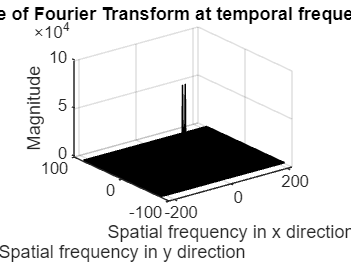

% Perform 3D Fourier Transform
H = fftn(surface_height);

% Calculate the magnitude
magnitude = abs(H);

% Define the frequency axes
[Nx, Ny, Nt] = size(H);
fx = linspace(-Nx/2, Nx/2-1, Nx); % Spatial frequencies in x direction
fy = linspace(-Ny/2, Ny/2-1, Ny); % Spatial frequencies in y direction
ft = linspace(-Nt/2, Nt/2-1, Nt); % Temporal frequencies

% Shift the zero frequency component to the center of the spectrum
magnitude_shifted = fftshift(magnitude);

% 3D surface plot for a specific temporal frequency slice
timeIndex = round(Nt / 2); % Mid-point in the temporal frequency domain
[X, Y] = meshgrid(fx, fy);
figure;
surf(transpose(X), transpose(Y), magnitude_shifted(:, :, timeIndex));
title(['Magnitude of Fourier Transform at temporal frequency index ', num2str(timeIndex)]);
xlabel('Spatial frequency in x direction');
ylabel('Spatial frequency in y direction');
zlabel('Magnitude');